Salary_dataset

Salary_dataset = 30×3 table
    Var1    YearsExperience    Salary
    ____    _______________    ______

      0           1.2          39344 
      1           1.4          46206 
      2           1.6          37732 
      3           2.1          43526 
      4           2.3          39892 
      5             3          56643 
      6           3.1          60151 
      7           3.3          54446 
      8           3.3          64446 
      9           3.8          57190 
     10             4          63219 
     11           4.1          55795 
     12           4.1          56958 
     13           4.2          57082 
     14           4.6          61112 
     15             5          67939 


Salary_dataset.Var1=[]

Salary_dataset = 30×2 table
    YearsExperience    Salary
    _______________    ______

          1.2          39344 
          1.4          46206 
          1.6          37732 
          2.1          43526 
          2.3          39892 
            3          56643 
          3.1          60151 
          3.3          54446 
          3.3          64446 
          3.8          57190 
            4          63219 
          4.1          55795 
          4.1          56958 
          4.2          57082 
          4.6          61112 
            5          67939 



summary(Salary_dataset)


Salary_dataset: 30×2 table

Variables:

    YearsExperience: double
    Salary: double

Statistics for applicable variables:

                       NumMissing       Min          Median          Max           Mean            Std      

    YearsExperience        0           1.2000        4.8000        10.6000        5.4133            2.8379  
    Salary                 0            37732         65238         122392         76004        2.7414e+04  



## Visualize

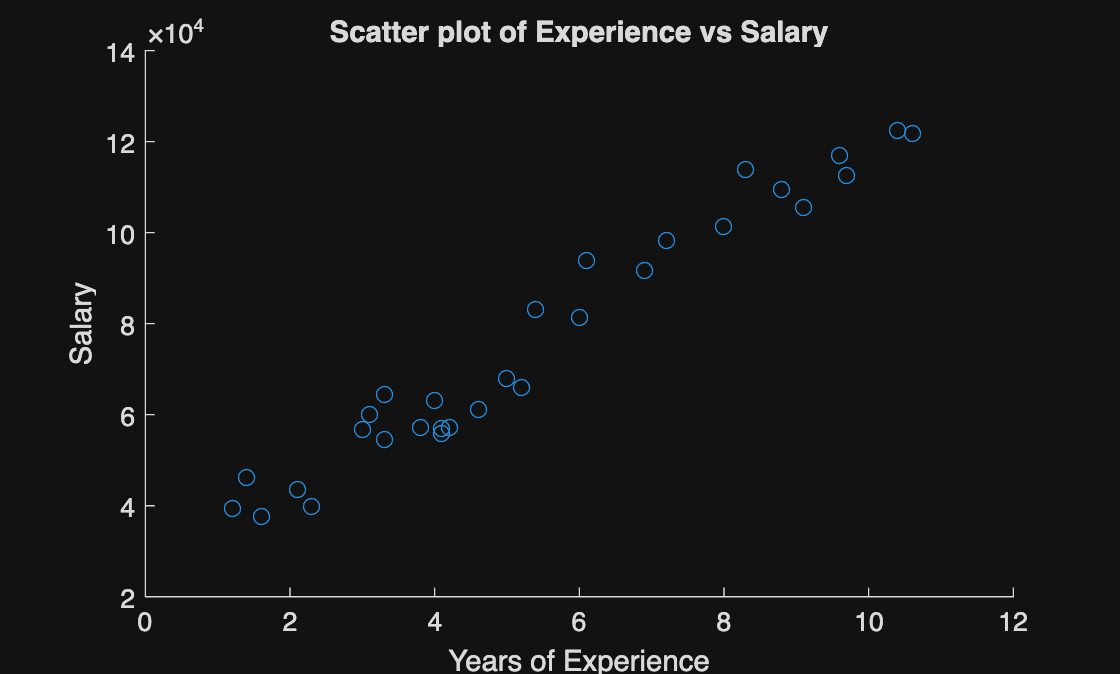

scatter(Salary_dataset.YearsExperience, Salary_dataset.Salary);
xlabel('Years of Experience');
ylabel('Salary');
title('Scatter plot of Experience vs Salary');

## Linear Regression Using Stats and ML Toolbox

mdl = fitlm(Salary_dataset, 'Salary ~ YearsExperience');

% Display model summary
disp(mdl);


Linear regression model:
    Salary ~ 1 + YearsExperience

Estimated Coefficients:
                       Estimate      SE      tStat       pValue  
                       ________    ______    ______    __________

    (Intercept)         24848      2306.7    10.772    1.8165e-11
    YearsExperience      9450      378.75     24.95    1.1431e-20


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 5.79e+03
R-squared: 0.957,  Adjusted R-Squared: 0.955
F-statistic vs. constant model: 623, p-value = 1.14e-20


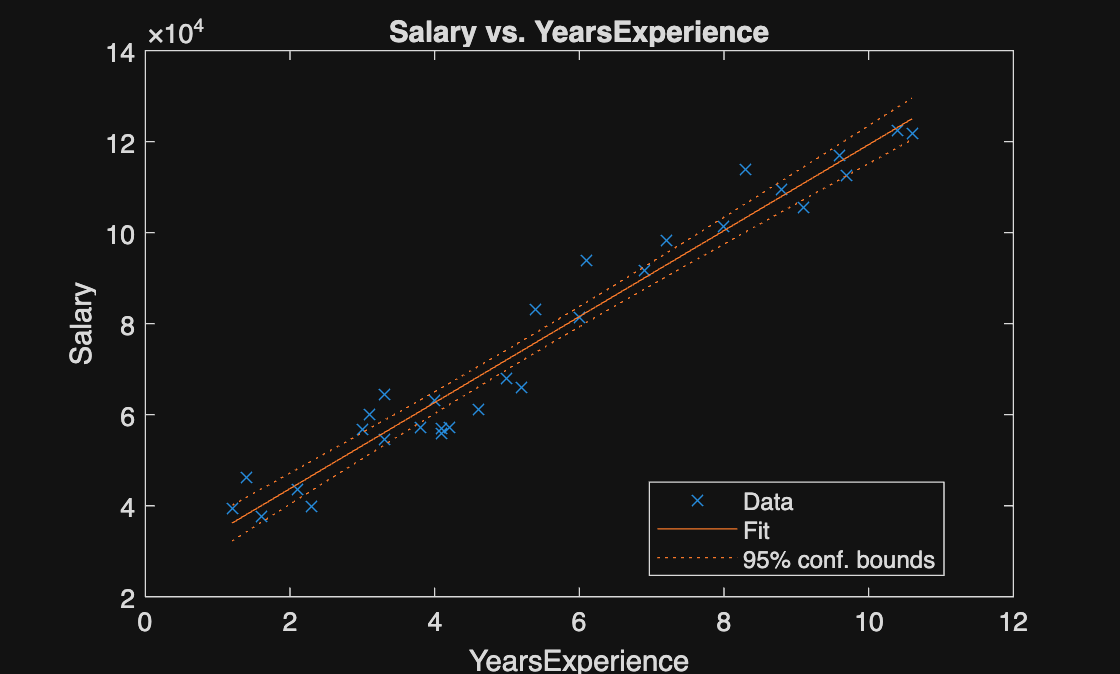


figure;
plot(mdl)


fprintf('Toolbox RMSE: %.4f\n', mdl.RMSE);

Toolbox RMSE: 5788.3151


fprintf('Toolbox R²: %.4f\n', mdl.Rsquared.Ordinary);

Toolbox R²: 0.9570


## Linear Regression from Scratch

x=Salary_dataset.YearsExperience;
y=Salary_dataset.Salary;

x_mean=mean(x);
y_mean=mean(y);

beta_1=sum((x-x_mean).*(y-y_mean));
beta_1=beta_1/sum((x-x_mean).^2);

beta_0=y_mean-beta_1*x_mean

beta_0 = 2.4848e+04


fprintf('Intercept (β₀): %.4f\n', beta_0);

Intercept (β₀): 24848.2040


fprintf('Slope (β₁): %.4f\n', beta_1);

Slope (β₁): 9449.9623


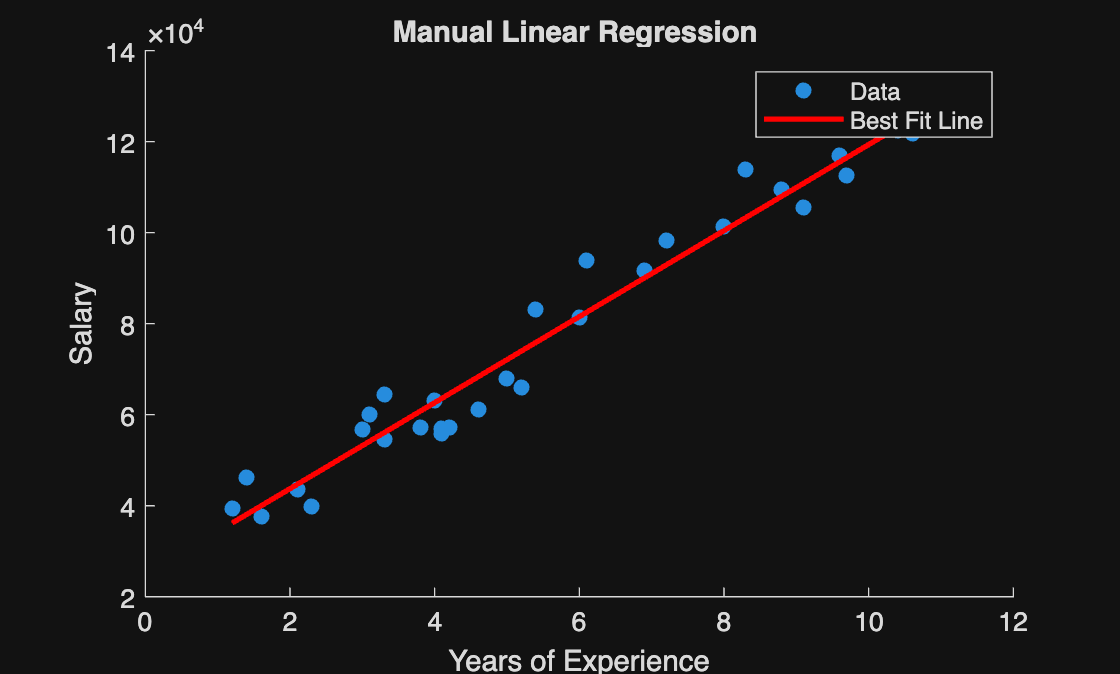



y_pred = beta_0 + beta_1 * x;


scatter(x, y, 'filled');
hold on;
plot(x, y_pred, 'r-', 'LineWidth', 2);
xlabel('Years of Experience');
ylabel('Salary');
title('Manual Linear Regression ');
legend('Data', 'Best Fit Line');
hold off;


% Evaluate model
residuals = y - y_pred;
rmse = sqrt(mean(residuals.^2));
R2 = 1 - sum(residuals.^2) / sum((y - y_mean).^2);
fprintf('Manual RMSE: %.4f\n', rmse);

Manual RMSE: 5592.0436


fprintf('Manual R²: %.4f\n', R2);

Manual R²: 0.9570
